General Symbolic Variables

syms g L_1 L_2

Full manipulator dynamics:


$$\begin{array}{l}
M\left(\mathit{\mathbf{q}}\right)\mathit{\mathbf{q}}+C_a \left(\mathit{\mathbf{q}}\right){\dot{\mathit{\mathbf{q}}} }_a +C_b \left(\mathit{\mathbf{q}}\right){\dot{\mathit{\mathbf{q}}} }_b +G\left(\mathit{\mathbf{q}}\right)=\tau \\
\mathit{\mathbf{q}}=\left\lbrack \begin{array}{c}
{\mathit{\mathbf{q}}}_1 \\
\vdots \\
{\mathit{\mathbf{q}}}_n 
\end{array}\right\rbrack ,\;\dot{\mathit{\mathbf{q}}} {\dot{\mathit{\mathbf{q}}} }^{\top } =\left\lbrack \begin{array}{ccc}
{\dot{q} }_1 {\dot{q} }_1  & \cdots  & {\dot{q} }_1 {\dot{q} }_n \\
\vdots  & \ddots  & \vdots \\
{\dot{q} }_n {\dot{q} }_1  & \cdots  & {\dot{q} }_n {\dot{q} }_n 
\end{array}\right\rbrack \\
\;{\dot{\mathit{\mathbf{q}}} }_a =\dot{\mathit{\mathbf{q}}} {\dot{\mathit{\mathbf{q}}} }^{\top } \;\textrm{where}\;\left(i=j\right)\\
\;{\dot{\mathit{\mathbf{q}}} }_b =\dot{\mathit{\mathbf{q}}} {\dot{\mathit{\mathbf{q}}} }^{\top } \;\textrm{where}\;\left(i\not= j\right)-\;\textrm{unique}\;\textrm{terms}\;\textrm{only}
\end{array}$$


$M$ = Mass matrix

$C_a$ = Centripetal matrix

$C_b$ = Coriolis matrix

$G$ = Gravitational matrix

$\tau$ = Generalized torques

Dynamics Derivation For Decoupled Belt Drive

syms L__d_g1 L__d_g2 m__d_1 m__d_2 I__d_1 I__d_2 I__d_m1 n_1 I__d_m2 n_2
syms psi_1 psi_dot_1 psi_ddot_1 psi_2 psi_dot_2 psi_ddot_2
syms tau__d_1 tau__d_2

q_psi = [psi_1 psi_dot_1 psi_ddot_1; psi_2 psi_dot_2 psi_ddot_2];

r_O_A = L__d_g1*[cos(psi_1); sin(psi_1);];
r_O_B = L_1*[cos(psi_1); sin(psi_1);];
r_O_C = [L_1*cos(psi_1)+L__d_g2*cos(psi_2); L_1*sin(psi_1)+L__d_g2*sin(psi_2);];
r_O_D = [L_1*cos(psi_1)+L_2*cos(psi_2); L_1*sin(psi_1)+L_2*sin(psi_2);];

omega_1 = [0; 0; psi_dot_1];
V_A = cross_2d(omega_1,r_O_A);
omega_2 = [0; 0; psi_dot_2];
V_C = cross_2d(omega_1,r_O_B) + cross_2d(omega_2,r_O_C-r_O_B);

V_A_mag_sq = mag_2d(V_A)^2;
V_C_mag_sq = mag_2d(V_C)^2;

V_C_mag_sq = simplify(expand(V_C_mag_sq));

T_trans = 1/2*m__d_1*V_A_mag_sq + 1/2*m__d_2*V_C_mag_sq;
T_rot = 1/2*I__d_1*psi_dot_1^2 + 1/2*I__d_2*psi_dot_2^2 + 1/2*I__d_m1*(n_1*psi_dot_1)^2 + 1/2*I__d_m2*(n_2*psi_dot_2)^2;
T = T_trans + T_rot;
V = m__d_1*g*L__d_g1*sin(psi_1) + m__d_2*g*(L_1*sin(psi_1) + L__d_g2*sin(psi_2));

lagrange_d = T-V;
Q_d = [tau__d_1; tau__d_2];
EOM_d = calc_lagrange(lagrange_d,q_psi,Q_d);
[M_d, Ca_d, Cb_d, G_d] = export_matrices(EOM_d,q_psi)

$$M\_d = \left(\begin{array}{cc} m_{2}^{d}\,{L_{1}}^{2}+m_{1}^{d}\,{L_{\mathrm{g1}}^{d}}^{2}+I_{\mathrm{m1}}^{d}\,{n_{1}}^{2}+I_{1}^{d} & L_{1}\,L_{\mathrm{g2}}^{d}\,m_{2}^{d}\,\cos\left(\psi_{1}-\psi_{2}\right)\\ L_{1}\,L_{\mathrm{g2}}^{d}\,m_{2}^{d}\,\cos\left(\psi_{1}-\psi_{2}\right) & m_{2}^{d}\,{L_{\mathrm{g2}}^{d}}^{2}+I_{\mathrm{m2}}^{d}\,{n_{2}}^{2}+I_{2}^{d} \end{array}\right)$$

$$Ca\_d = \left(\begin{array}{cc} 0 & L_{1}\,L_{\mathrm{g2}}^{d}\,m_{2}^{d}\,\sin\left(\psi_{1}-\psi_{2}\right)\\ -L_{1}\,L_{\mathrm{g2}}^{d}\,m_{2}^{d}\,\sin\left(\psi_{1}-\psi_{2}\right) & 0 \end{array}\right)$$

$$Cb\_d = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

$$G\_d = \left(\begin{array}{c} g\,\cos\left(\psi_{1}\right)\,\left(L_{1}\,m_{2}^{d}+L_{\mathrm{g1}}^{d}\,m_{1}^{d}\right)\\ L_{\mathrm{g2}}^{d}\,g\,m_{2}^{d}\,\cos\left(\psi_{2}\right) \end{array}\right)$$

Dynamics Derivation for Standard Serial Link (Infants leg)

syms L__i_g1 L__i_g2 m__i_1 m__i_2 I__i_1 I__i_2
syms theta_1 theta_dot_1 theta_ddot_1 theta_2 theta_dot_2 theta_ddot_2
syms tau__i_1 tau__i_2

q_theta = [theta_1 theta_dot_1 theta_ddot_1; theta_2 theta_dot_2 theta_ddot_2];

r_O_A = L__i_g1*[cos(theta_1); sin(theta_1);];
r_O_B = L_1*[cos(theta_1); sin(theta_1);];

omega_1 = [0; 0; theta_dot_1];
V_A = cross_2d(omega_1,r_O_A);

J_C = [-L_1*sin(theta_1)-L__i_g2*sin(theta_1+theta_2) -L__i_g2*sin(theta_1+theta_2);
       L_1*cos(theta_1)+L__i_g2*cos(theta_1+theta_2) L__i_g2*cos(theta_1+theta_2)];
V_C = J_C*[theta_dot_1; theta_dot_2];

V_A_mag_sq = mag_2d(V_A)^2;
V_C_mag_sq = mag_2d(V_C)^2;

V_C_mag_sq = simplify(expand(V_C_mag_sq));

T_trans = 1/2*m__i_1*V_A_mag_sq + 1/2*m__i_2*V_C_mag_sq;
T_rot = 1/2*I__i_1*theta_dot_1^2 + 1/2*I__i_2*(theta_dot_1+theta_dot_2)^2;
T = T_trans + T_rot;
V = m__i_1*g*L__i_g1*sin(theta_1) + m__i_2*g*(L_1*sin(theta_1) + L__i_g2*sin(theta_1+theta_2));

lagrange_i = T-V;
Q_i = [tau__i_1; tau__i_2];
EOM_i = calc_lagrange(lagrange_i,q_theta,Q_i)

$$EOM\_i = \begin{array}{l} \left(\begin{array}{c} \left(m_{2}^{i}\,{L_{1}}^{2}+2\,m_{2}^{i}\,\cos\left(\theta_{2}\right)\,L_{1}\,L_{\mathrm{g2}}^{i}+m_{1}^{i}\,{L_{\mathrm{g1}}^{i}}^{2}+m_{2}^{i}\,{L_{\mathrm{g2}}^{i}}^{2}+I_{1}^{i}+I_{2}^{i}\right)\,{\ddot{\theta }}_{1}+\left(-2\,L_{1}\,L_{\mathrm{g2}}^{i}\,m_{2}^{i}\,{\dot{\theta }}_{2}\,\sin\left(\theta_{2}\right)\right)\,{\dot{\theta }}_{1}+I_{2}^{i}\,{\ddot{\theta }}_{2}+{L_{\mathrm{g2}}^{i}}^{2}\,m_{2}^{i}\,{\ddot{\theta }}_{2}+\sigma_{1}+L_{1}\,g\,m_{2}^{i}\,\cos\left(\theta_{1}\right)+L_{\mathrm{g1}}^{i}\,g\,m_{1}^{i}\,\cos\left(\theta_{1}\right)-L_{1}\,L_{\mathrm{g2}}^{i}\,m_{2}^{i}\,{{\dot{\theta }}_{2}}^{2}\,\sin\left(\theta_{2}\right)+L_{1}\,L_{\mathrm{g2}}^{i}\,m_{2}^{i}\,{\ddot{\theta }}_{2}\,\cos\left(\theta_{2}\right)=\tau_{1}^{i}\\ \left(m_{2}^{i}\,{L_{\mathrm{g2}}^{i}}^{2}+I_{2}^{i}\right)\,{\ddot{\theta }}_{2}+I_{2}^{i}\,{\ddot{\theta }}_{1}+{L_{\mathrm{g2}}^{i}}^{2}\,m_{2}^{i}\,{\ddot{\theta }}_{1}+\sigma_{1}+L_{1}\,L_{\mathrm{g2}}^{i}\,m_{2}^{i}\,{{\dot{\theta }}_{1}}^{2}\,\sin\left(\theta_{2}\right)+L_{1}\,L_{\mathrm{g2}}^{i}\,m_{2}^{i}\,{\ddot{\theta }}_{1}\,\cos\left(\theta_{2}\right)=\tau_{2}^{i} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{\mathrm{g2}}^{i}\,g\,m_{2}^{i}\,\cos\left(\theta_{1}+\theta_{2}\right) \end{array}$$

[M_i, Ca_i, Cb_i, G_i] = export_matrices(EOM_i,q_theta)

$$M\_i = \left(\begin{array}{cc} m_{2}^{i}\,{L_{1}}^{2}+2\,m_{2}^{i}\,\cos\left(\theta_{2}\right)\,L_{1}\,L_{\mathrm{g2}}^{i}+m_{1}^{i}\,{L_{\mathrm{g1}}^{i}}^{2}+m_{2}^{i}\,{L_{\mathrm{g2}}^{i}}^{2}+I_{1}^{i}+I_{2}^{i} & m_{2}^{i}\,{L_{\mathrm{g2}}^{i}}^{2}+L_{1}\,m_{2}^{i}\,\cos\left(\theta_{2}\right)\,L_{\mathrm{g2}}^{i}+I_{2}^{i}\\ m_{2}^{i}\,{L_{\mathrm{g2}}^{i}}^{2}+L_{1}\,m_{2}^{i}\,\cos\left(\theta_{2}\right)\,L_{\mathrm{g2}}^{i}+I_{2}^{i} & m_{2}^{i}\,{L_{\mathrm{g2}}^{i}}^{2}+I_{2}^{i} \end{array}\right)$$

$$Ca\_i = \left(\begin{array}{cc} 0 & -L_{1}\,L_{\mathrm{g2}}^{i}\,m_{2}^{i}\,\sin\left(\theta_{2}\right)\\ L_{1}\,L_{\mathrm{g2}}^{i}\,m_{2}^{i}\,\sin\left(\theta_{2}\right) & 0 \end{array}\right)$$

$$Cb\_i = \left(\begin{array}{c} -2\,L_{1}\,L_{\mathrm{g2}}^{i}\,m_{2}^{i}\,\sin\left(\theta_{2}\right)\\ 0 \end{array}\right)$$

$$G\_i = \left(\begin{array}{c} g\,\left(L_{\mathrm{g2}}^{i}\,m_{2}^{i}\,\cos\left(\theta_{1}+\theta_{2}\right)+L_{1}\,m_{2}^{i}\,\cos\left(\theta_{1}\right)+L_{\mathrm{g1}}^{i}\,m_{1}^{i}\,\cos\left(\theta_{1}\right)\right)\\ L_{\mathrm{g2}}^{i}\,g\,m_{2}^{i}\,\cos\left(\theta_{1}+\theta_{2}\right) \end{array}\right)$$

Combine full system (Device + Infant Leg) by converting theta to psi for the infant EOM

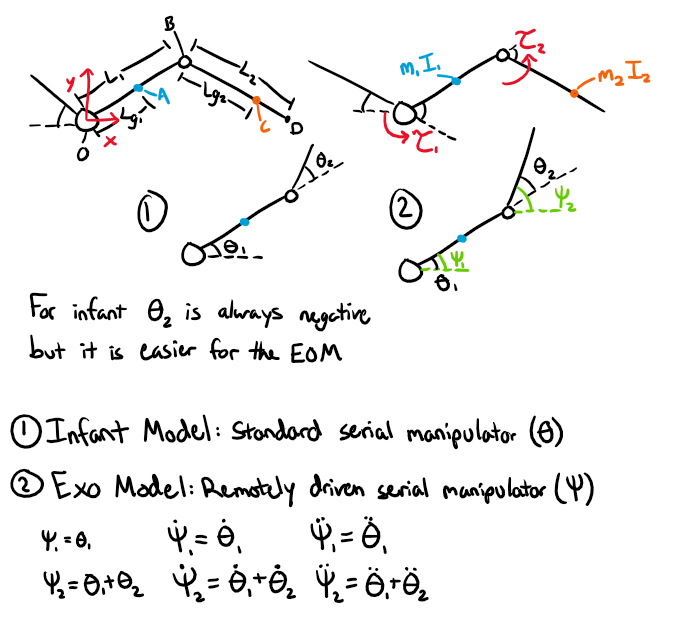

theta_vars = [theta_1 theta_2...
              theta_dot_1 theta_dot_2...
              theta_ddot_1 theta_ddot_2];

psi_vars = [psi_1 psi_2-psi_1...
            psi_dot_1 psi_dot_2-psi_dot_1...
            psi_ddot_1 psi_ddot_2-psi_ddot_1];

EOM_i_psi = subs(EOM_i,theta_vars,psi_vars);
[M_i_psi, Ca_i_psi, Cb_i_psi, G_i_psi] = export_matrices(EOM_i_psi,q_psi);

EOM_d;
EOM_i;
EOM_i_psi;
EOM_full = EOM_i_psi + EOM_d

[M_f, Ca_f, Cb_f, G_f] = export_matrices(EOM_full,q_psi)

$$M\_f = \left(\begin{array}{cc} I_{1}^{d}+I_{1}^{i}+I_{\mathrm{m1}}^{d}\,{n_{1}}^{2}+{L_{1}}^{2}\,m_{2}^{d}+{L_{1}}^{2}\,m_{2}^{i}+{L_{\mathrm{g1}}^{d}}^{2}\,m_{1}^{d}+{L_{\mathrm{g1}}^{i}}^{2}\,m_{1}^{i}+L_{1}\,L_{\mathrm{g2}}^{i}\,m_{2}^{i}\,\cos\left(\psi_{1}-\psi_{2}\right) & m_{2}^{i}\,{L_{\mathrm{g2}}^{i}}^{2}+L_{1}\,m_{2}^{i}\,\cos\left(\psi_{1}-\psi_{2}\right)\,L_{\mathrm{g2}}^{i}+I_{2}^{i}+L_{1}\,L_{\mathrm{g2}}^{d}\,m_{2}^{d}\,\cos\left(\psi_{1}-\psi_{2}\right)\\ L_{1}\,\cos\left(\psi_{1}-\psi_{2}\right)\,\left(L_{\mathrm{g2}}^{d}\,m_{2}^{d}+L_{\mathrm{g2}}^{i}\,m_{2}^{i}\right) & m_{2}^{d}\,{L_{\mathrm{g2}}^{d}}^{2}+m_{2}^{i}\,{L_{\mathrm{g2}}^{i}}^{2}+I_{\mathrm{m2}}^{d}\,{n_{2}}^{2}+I_{2}^{d}+I_{2}^{i} \end{array}\right)$$

$$Ca\_f = \left(\begin{array}{cc} -L_{1}\,L_{\mathrm{g2}}^{i}\,m_{2}^{i}\,\sin\left(\psi_{1}-\psi_{2}\right) & L_{1}\,\sin\left(\psi_{1}-\psi_{2}\right)\,\left(L_{\mathrm{g2}}^{d}\,m_{2}^{d}+L_{\mathrm{g2}}^{i}\,m_{2}^{i}\right)\\ -L_{1}\,\sin\left(\psi_{1}-\psi_{2}\right)\,\left(L_{\mathrm{g2}}^{d}\,m_{2}^{d}+L_{\mathrm{g2}}^{i}\,m_{2}^{i}\right) & 0 \end{array}\right)$$

$$Cb\_f = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

$$G\_f = \left(\begin{array}{c} g\,\left(L_{1}\,m_{2}^{d}\,\cos\left(\psi_{1}\right)+L_{1}\,m_{2}^{i}\,\cos\left(\psi_{1}\right)+L_{\mathrm{g1}}^{d}\,m_{1}^{d}\,\cos\left(\psi_{1}\right)+L_{\mathrm{g1}}^{i}\,m_{1}^{i}\,\cos\left(\psi_{1}\right)+L_{\mathrm{g2}}^{i}\,m_{2}^{i}\,\cos\left(\psi_{2}\right)\right)\\ g\,\cos\left(\psi_{2}\right)\,\left(L_{\mathrm{g2}}^{d}\,m_{2}^{d}+L_{\mathrm{g2}}^{i}\,m_{2}^{i}\right) \end{array}\right)$$